% Define the file name and open the file for reading
filename = 'scope_0.csv';


% Read the LTSpice data as a table
data = readtable(filename, 'Delimiter', ','); % Assuming tab-delimited data

time = data.Var1;
input = data.Var2;
output = data.Var3;

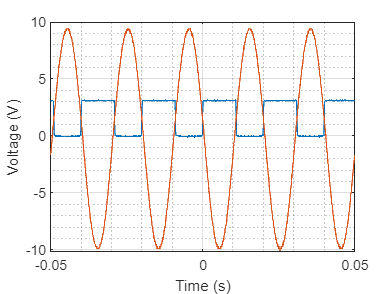

figure;

plot(time, input);
xlabel('Time (s)');
ylabel('Voltage (V)');
grid on
grid minor

hold on

plot(time, output);

hold off


max(input)

ans = 3.1558

min(input)

ans = -0.1407

max(output)

ans = 9.3970

min(output)

ans = -10.1005

% Define the file name and open the file for reading
filename = 'data.txt';


% Read the LTSpice data as a table
trans_data = readtable(filename, 'Delimiter', ','); % Assuming tab-delimited data

Error using readtable
Unable to find or open 'data.txt'. Check the path and filename or file
permissions.


numel(trans_data.Var3)

ans = 3891

trans_data.Var3([numel(trans_data.Var3)])

ans = 2885